# Ingresso multisinusoidi con sfasamento casuale e ampiezza casuale

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi
st=1e-3;


## Sfasamento casuale

#### Portante

omega_portante=0.05;
ampiezza_portante=1.5;
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Multisinusoidi:

Scelgo le sinusoidi come un vettore logaritmicamente spaziato (potrei infittirlo nelle zone di interesse)

w0=0.5;
w1=1500;
omega=logspace(log10(w0),log10(w1),60)';

arrotondo a dei multipli della portante

omega=round(omega/omega_portante)*omega_portante; % arrotondo per avere le omega multiple della portante

Rimuovo duplicati

omega=unique(omega); %scarto eventuali doppioni

Credo il segnale come somma di sinusoidi (qui suppongo ampiezza costante per ogni pulsazione, nulla mi impedisce di fare diversamente)

multisine_signal=zeros(length(t),1);
for idx=1:length(omega)
    multisine_signal=multisine_signal+sin(omega(idx)*t);
end

Impongo che l'ampiezza del segnale sia quella desiderata

max_applitude=2;
multisine_signal=multisine_signal/max(multisine_signal)*max_applitude;

Sommo i due segnali

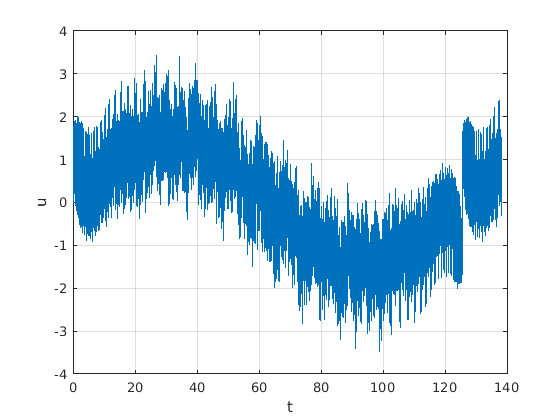

control_action=portante+ multisine_signal;

plot(t,control_action)
grid on
xlabel('t')
ylabel('u')

Il segnale ha un andamento molto bruso attorno a fine periodo, tutte le armoniche si annullano contemporaneamente. Posso migliorarlo randomizzando la fare

multisine_signal_2=zeros(length(t),1);
for idx=1:length(omega)
    fase=rand*2*pi; % sfasamento random. sin(alpha-beta)= cos()sin()-sin()cos() wiki 
    coeff_sin=sin(fase);
    coeff_cos=cos(fase);
    multisine_signal_2=multisine_signal_2+coeff_sin*sin(omega(idx)*t)+coeff_cos*cos(omega(idx)*t);
end

Impongo che l'ampiezza del segnale sia quella desiderata

max_applitude=2;
multisine_signal_2=multisine_signal_2/max(multisine_signal_2)*max_applitude;

Sommo i due segnali

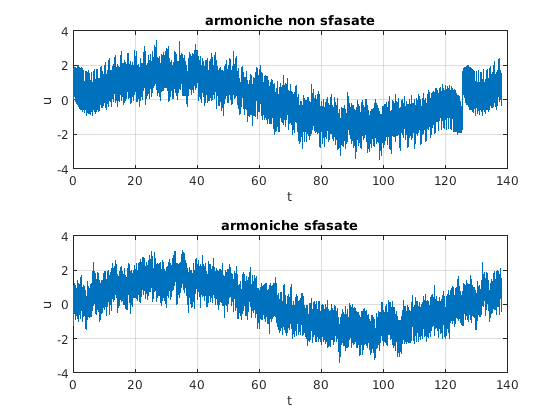

control_action_2=portante+ multisine_signal_2;

figure
tiledlayout(2,1)
nexttile
plot(t,control_action)
grid on
xlabel('t')
ylabel('u')
title('armoniche non sfasate')
nexttile
plot(t,control_action_2)
grid on
xlabel('t')
ylabel('u')
title('armoniche sfasate')

Coefficienti di Fourier 

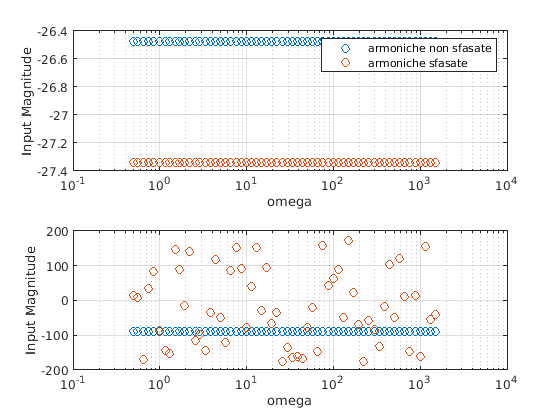

control_action_coef=fourierCoefficients(t,control_action,omega_portante,omega);
control_action_coef_2=fourierCoefficients(t,control_action_2,omega_portante,omega);

figure
subplot(2,1,1)
semilogx(omega,20*log10(abs(control_action_coef)),'o')
hold on
semilogx(omega,20*log10(abs(control_action_coef_2)),'o')
hold off
grid on
xlabel('omega')
ylabel('Input Magnitude')
legend('armoniche non sfasate','armoniche sfasate')

subplot(2,1,2)
semilogx(omega,rad2deg(angle(control_action_coef)),'o')
hold on
semilogx(omega,rad2deg(angle(control_action_coef_2)),'o')
hold off
grid on
xlabel('omega')
ylabel('Input Magnitude')

**Nota 1**: i coefficienti nel caso con armoniche sfalsate sono maggiori perchè lo sfasamento riduce la possibilità che i valori di picco delle singole armoniche capitino nello stesso tempo.

##  Ampiezza casuale

per introdurre ancora più variabilità nel test è possibile variare anche l'ampiezza delle singole armoniche

multisine_signal_3=zeros(length(t),1);
for idx=1:length(omega)
    fase=rand*2*pi;
    ampiezza_relativa=0.5+0.5*rand; % fra 0.5 e 1
    coeff_sin=sin(fase)*ampiezza_relativa;
    coeff_cos=cos(fase)*ampiezza_relativa;
    multisine_signal_3=multisine_signal_3+coeff_sin*sin(omega(idx)*t)+coeff_cos*cos(omega(idx)*t);
end

Impongo che l'ampiezza del segnale sia quella desiderata

max_applitude=2;
multisine_signal_3=multisine_signal_3/max(multisine_signal_3)*max_applitude;

Sommo i due segnali

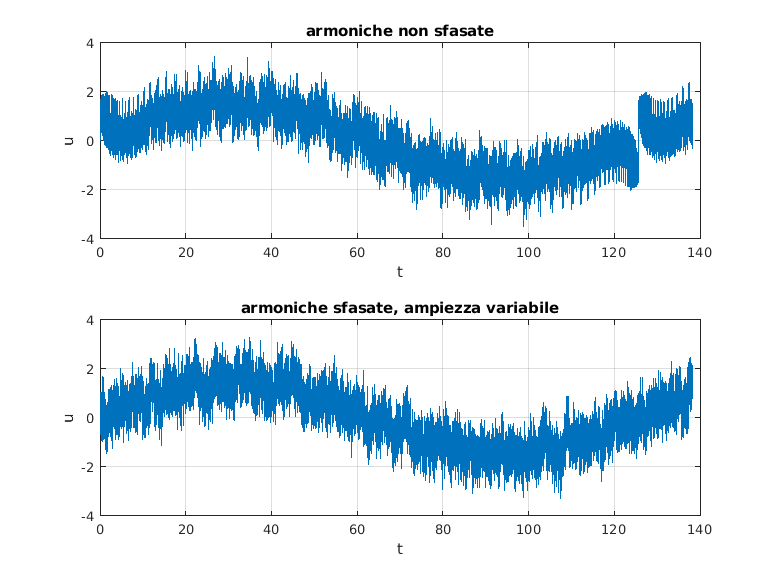

control_action_3=portante+ multisine_signal_3;

figure
tiledlayout(2,1)
nexttile
plot(t,control_action)
grid on
xlabel('t')
ylabel('u')
title('armoniche non sfasate')
nexttile
plot(t,control_action_3)
grid on
xlabel('t')
ylabel('u')
title('armoniche sfasate, ampiezza variabile')

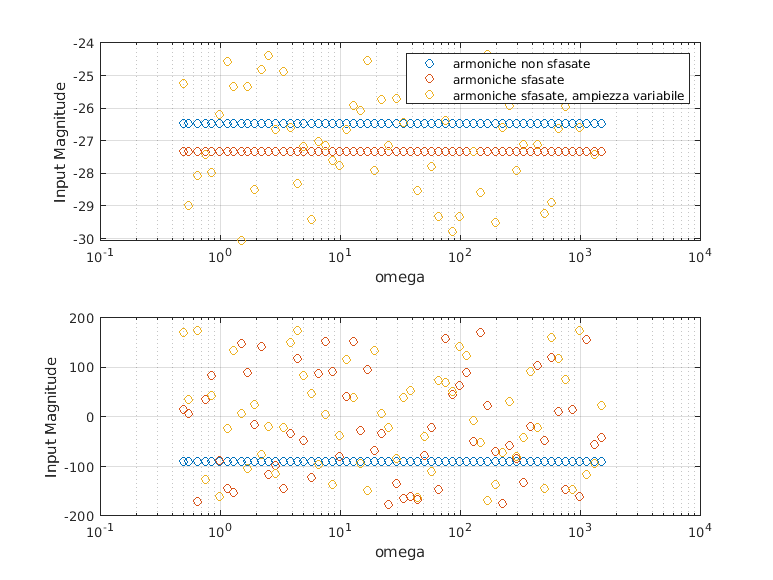

control_action_coef_3=fourierCoefficients(t,control_action_3,omega_portante,omega);

figure
subplot(2,1,1)
semilogx(omega,20*log10(abs(control_action_coef)),'o')
hold on
semilogx(omega,20*log10(abs(control_action_coef_2)),'o')
semilogx(omega,20*log10(abs(control_action_coef_3)),'o')
hold off
grid on
xlabel('omega')
ylabel('Input Magnitude')
legend('armoniche non sfasate','armoniche sfasate','armoniche sfasate, ampiezza variabile')

subplot(2,1,2)
semilogx(omega,rad2deg(angle(control_action_coef)),'o')
hold on
semilogx(omega,rad2deg(angle(control_action_coef_2)),'o')
semilogx(omega,rad2deg(angle(control_action_coef_3)),'o')
hold off
grid on
xlabel('omega')
ylabel('Input Magnitude')